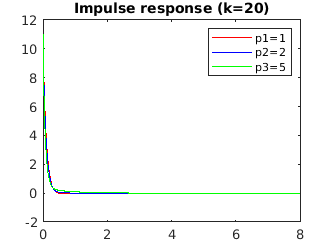

% K=20
%  PES1UG20EC083 JACOB V SANOJ
% QUESTION 6B
% impulse reference response
clc;
clear all;
close all;
t=0:0.01:8;
p1 = 1;
p2 = 2;
p3 = 5;
k1=20;
g1=[0 11 k1];
num1=tf(conv(g1,[0 0 1]),[1 p1 0]);
num2=tf(conv(g1,[0 0 1]),[1 p2 0]);
num3=tf(conv(g1,[0 0 1]),[1 p3 0]);
den1=1+num1;
den2=1+num2;
den3=1+num3;
[N1,~]=tfdata(num1);
[N2,~]=tfdata(num2);
[N3,~]=tfdata(num3);
[n1,~]=tfdata(den1);
[n2,~]=tfdata(den2);
[n3,~]=tfdata(den3);
tf1=tf(N1,n1);
tf2=tf(N2,n2);
tf3=tf(N3,n3);
y1=impulse(tf1,t);
y2=impulse(tf2,t);
y3=impulse(tf3,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Impulse response (k=20)')
legend('p1=1','p2=2','p3=5')

t1=risetime(y1)


t1 =

     []



t2=risetime(y2)


t2 =

     []



t3=risetime(y3)


t3 =

     []



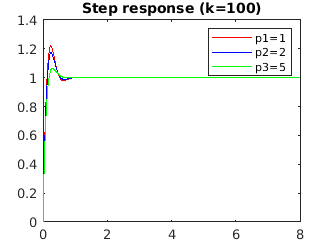

% step reference response
clc;
clear all;
close all;
t=0:0.01:8;
p1 = 1;
p2 = 2;
p3 = 5;
k1=100;
g1=[0 11 k1];
num1=tf(conv(g1,[0 0 1]),[1 p1 0]);
num2=tf(conv(g1,[0 0 1]),[1 p2 0]);
num3=tf(conv(g1,[0 0 1]),[1 p3 0]);
den1=1+num1;
den2=1+num2;
den3=1+num3;
[N1,~]=tfdata(num1);
[N2,~]=tfdata(num2);
[N3,~]=tfdata(num3);
[n1,~]=tfdata(den1);
[n2,~]=tfdata(den2);
[n3,~]=tfdata(den3);
tf1=tf(N1,n1);
tf2=tf(N2,n2);
tf3=tf(N3,n3);
y1=step(tf1,t);
y2=step(tf2,t);
y3=step(tf3,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Step response (k=100)')
legend('p1=1','p2=2','p3=5')

t1=risetime(y1)

t1 = 9.6015

t2=risetime(y2)

t2 = 10.3817

t3=risetime(y3)

t3 = 12.7898

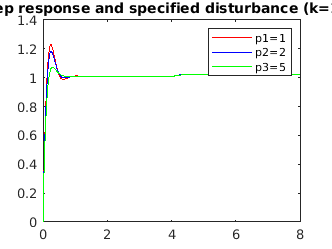

% step reference and a specified disturbance input
clc;
clear all;
close all;
t=0:0.01:8;
p1 = 1;
p2 = 2;
p3 = 5;
k1=100;
g1=[0 11 k1];
num1=tf(conv(g1,[0 0 1]),[1 p1 0]);
num2=tf(conv(g1,[0 0 1]),[1 p2 0]);
num3=tf(conv(g1,[0 0 1]),[1 p3 0]);
den1=1+num1;
den2=1+num2;
den3=1+num3;
[N1,~]=tfdata(num1);
[N2,~]=tfdata(num2);
[N3,~]=tfdata(num3);
[n1,~]=tfdata(den1);
[n2,~]=tfdata(den2);
[n3,~]=tfdata(den3);
tf1=tf(N1,n1);
tf2=tf(N2,n2);
tf3=tf(N3,n3);
yr1=step(tf1,t);
yr2=step(tf2,t);
yr3=step(tf3,t);
t1=tf([0 0 1],n1);
t2=tf([0 0 1],n2);
t3=tf([0 0 1],n3);
d = 0*t;
d(t>=0 & t<=4)=1;
d(t>4 & t<=8)=2;
yd1= lsim(t1,d,t);
yd2= lsim(t2,d,t);
yd3= lsim(t3,d,t);
y1=yr1+yd1;
y2=yr2+yd2;
y3=yr3+yd3;
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Step response and specified disturbance (k=100)')
legend('p1=1','p2=2','p3=5')

t1=risetime(y1)

t1 = 9.8361

t2=risetime(y2)

t2 = 10.6543

t3=risetime(y3)

t3 = 13.2025